%% Train NARX Network and Predict on New Data
clear all
load("..\..\doc\lab_3\narxnet_workspace.mat")

%%
% Partition the training data. Use |Xnew| to do prediction in closed
% loop mode later.
x_begin_sample = 702;
x_end_sample = 4801;

Theta = dane_NN_test2.signals(1).values;
X = Theta(x_begin_sample:x_end_sample)';
X = num2cell(X);

X_train = X(1:3000);
Xnew = X(1000:2050);
Xnew = X(3000:4050);



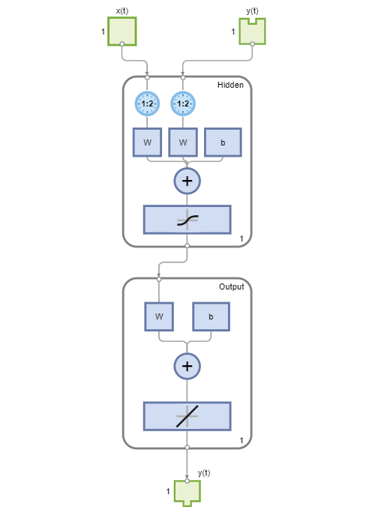

%%
% Train a network, and simulate it on the first 80 observations
net = narxnet(1:2,1:2,1);
[Xs,Xi,Ai,Ts] = preparets(net,X_train,{},X_train);

net.divideFcn = 'dividetrain';
net.trainFcn = 'trainbr';

net = train(net,Xs,Ts,Xi,Ai);
view(net)


%%
% Calculate the network performance.
[Y,Xf,Af] = net(Xs,Xi,Ai);
perf = perform(net,Ts,Y)

perf = 1.0698e-07

Y_num = cell2mat(Y)

Y_num =     0.2471    0.2845    0.3219    0.3593    0.3954    0.4328    0.4686    0.5050    0.5408    0.5770    0.6118    0.6473    0.6828    0.7171    0.7519    0.7862    0.8201    0.8537    0.8870    0.9200    0.9539    0.9856    1.0170    1.0478    1.0805    1.1106    1.1411    1.1713    1.2011    1.2300    1.2595    1.2878    1.3167    1.3437    1.3716    1.3977    1.4247    1.4505    1.4768    1.5013    1.5268    1.5516    1.5755    1.5993    1.6222    1.6452    1.6678    1.6894    1.7111    1.7325


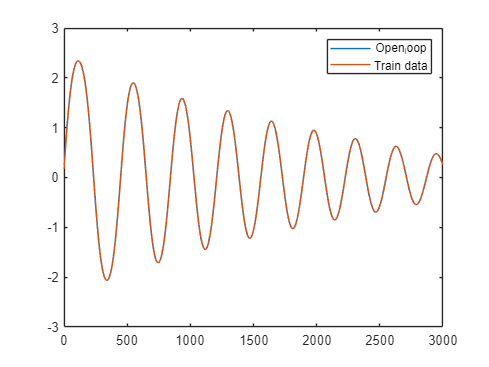


figure(11);
plot(Y_num)
hold on
plot(cell2mat(X_train))
legend('Open_loop', 'Train data')
hold off

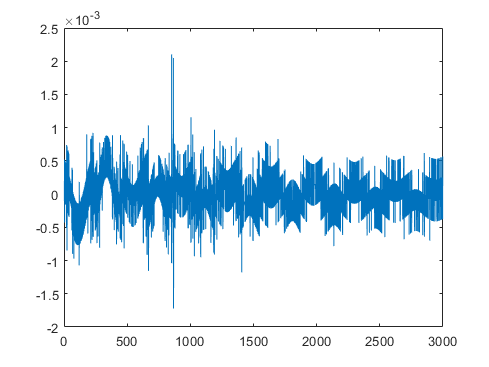


figure(12); plot(Y_num - cell2mat(X_train(3:end)))

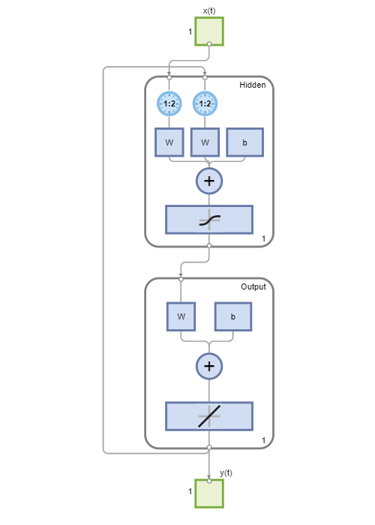

%%
% Run the prediction for 20 time steps ahead in closed loop mode.
[netc,Xic,Aic] = closeloop(net,Xf,Af);
view(netc)


%%
y2 = netc(Xnew,Xic,Aic)
yc_num = cell2mat(y2)

yc_num =     0.2478    0.2478    0.2441    0.2367    0.2271    0.2172    0.2082    0.1999    0.1921    0.1843    0.1763    0.1685    0.1601    0.1513    0.1426    0.1339    0.1254    0.1167    0.1085    0.0999    0.0913    0.0825    0.0736    0.0646    0.0561    0.0475    0.0387    0.0299    0.0210    0.0125    0.0038   -0.0049   -0.0135   -0.0222   -0.0310   -0.0396   -0.0483   -0.0568   -0.0652   -0.0735   -0.0820   -0.0904   -0.0986   -0.1070   -0.1152   -0.1232   -0.1313   -0.1394   -0.1473   -0.1553


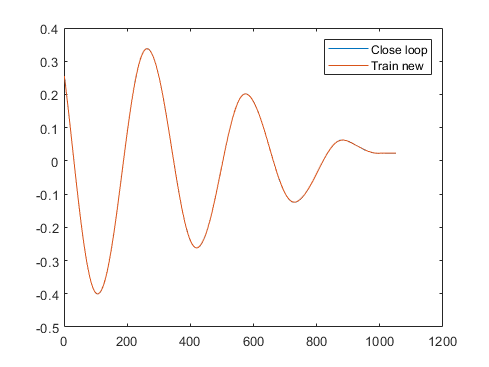

figure
plot(yc_num)
hold on 
plot(cell2mat(Xnew))
legend('Close loop', 'Train new')

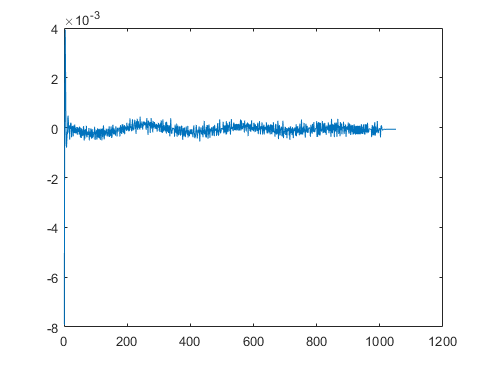

figure(12); plot(yc_num - cell2mat(Xnew))

MODEL HYBRYDOWY DO TESTOWANIA:

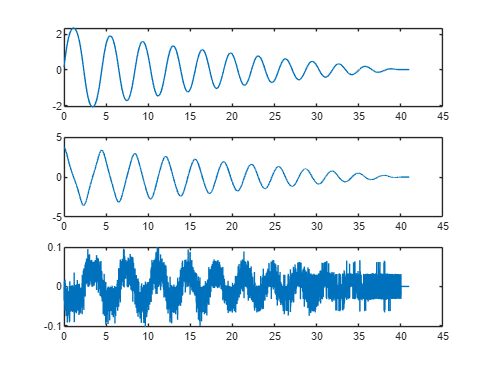

time = dane_NN_test2.time(x_begin_sample:x_end_sample) - dane_NN_test2.time(x_begin_sample);
x_1 = dane_NN_test2.signals(1).values(x_begin_sample:x_end_sample);
x_1_prim = dane_NN_test2.signals(4).values(x_begin_sample:x_end_sample);
x_2_prim = [0; diff(dane_NN_test2.signals(4).values(x_begin_sample:x_end_sample))];

figure
subplot(3, 1, 1)
plot(time, x_1)
subplot(3, 1, 2)
plot(time, x_1_prim)
subplot(3, 1, 3)
plot(time, x_2_prim)

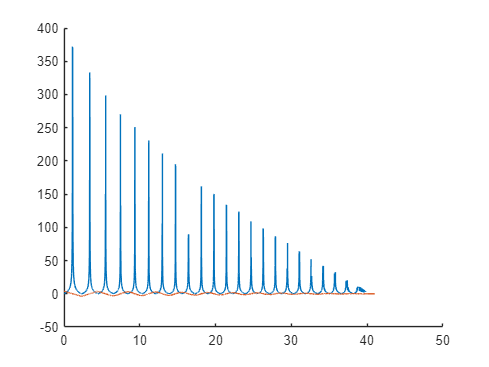

figure
hold on
plot(time, Beta_calculate(x_1, x_2_prim, x_1_prim))
plot(time, x_1_prim)
hold off

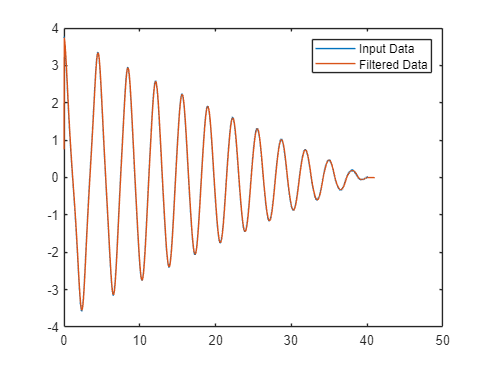

windowSize = 5; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

x_1_prim_filtered = filter(b,a,x_1_prim);

figure
plot(time,x_1_prim)
hold on
plot(time,x_1_prim_filtered)
legend('Input Data','Filtered Data')
hold off

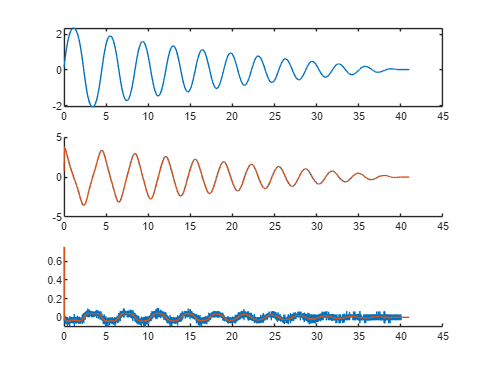

x_2_prim_filtered = [0; diff(x_1_prim_filtered)];

figure
subplot(3, 1, 1)
plot(time, x_1)
subplot(3, 1, 2)
hold on
plot(time, x_1_prim)
plot(time,x_1_prim_filtered)
hold off
subplot(3, 1, 3)
hold on
plot(time, x_2_prim)
plot(time, x_2_prim_filtered)
hold off

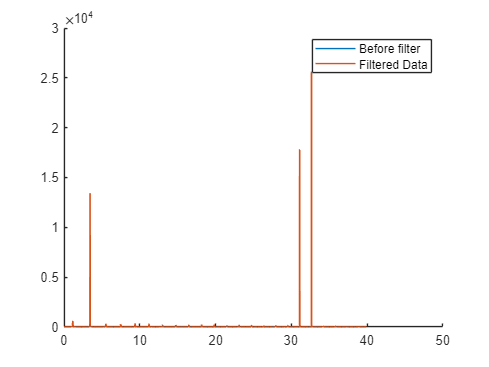

figure
hold on
plot(time, Beta_calculate(x_1, x_2_prim, x_1_prim))
plot(time, filter(b,a,Beta_calculate(x_1, x_2_prim_filtered, x_1_prim_filtered)))
legend('Before filter','Filtered Data')
hold off

function Beta_output = Beta_calculate(x_1, x_2_prim, x_2)
    alfa = -4.9764;
    Beta_output = abs((x_2_prim - alfa .* x_1)./x_2);
end